# Adapt Transfer Learning Network for Regression

This example shows how to use transfer learning to retrain a convolutional neural network to estimate a regression output for each image, based on the health condition of each sample tool.

Pretrained image classification networks have been trained on over a million images and can classify images into 1000 object categories, such as keyboard, coffee mug, pencil, and many animals. The networks have learned rich feature representations for a wide range of images. The network takes an image as input, and then outputs a label for the object in the image together with the probabilities for each of the object categories.

Transfer learning is commonly used in deep learning applications. You can take a pretrained network and use it as a starting point to learn a new task. Fine-tuning a network with transfer learning is usually much faster and easier than training a network from scratch with randomly initialized weights. You can quickly transfer learned features to a new task using a smaller number of training images.

## Load Data

Unzip and load the new images as an image datastore. This small data set contains only 327 images. Divide the data into training and validation data sets. Use 67% of the images for training and 33% for validation.

% prelabeledData = updatedDataTable(updatedDataTable.ylabel>0,:);
% load an array of the required data to model
rng('default');
load updatedDataTable.mat

% perform predictions based on the wear value of the image
knownLabelData = updatedDataTable(updatedDataTable.ylabel>0,:);
unknownLabelData = updatedDataTable(updatedDataTable.ylabel==0,:);

% our image datastore predictors are the prelabeledData.xLabel(:)
% essentially, our image datastore should not have labels
% imds = imageDatastore(prelabeledData.filename(:),'Labels',prelabeledData.xlabel(:));

% imds = imageDatastore(knownLabelData.filename(:));

data = table(table2array(knownLabelData(:,'filename')),normalize(table2array(knownLabelData(:,'ylabel')),'range',[0, 1]),'VariableNames',{'filename','ylabel'});
%unknownDataSubtable = table(unknownLabelData(:,'filename'),unknownLabelData(:,'xlabel'));

%ds = datastore(knownDataSubtable,'Type','image');
% idea: LabelSource: array of wear values

% imdsTrain = partition(ds,3,1);
% imdsTest = partition(ds,3,2);
% imdsValidation = partition(ds,3,3);
imdsTrain = data(1:218,:);
imdsValidation = data(219:327,:);
%imdsTest = data(219:327,:);

## Load Pretrained Network

Load a pretrained GoogLeNet network. If the Deep Learning Toolbox™ Model *for GoogLeNet Network* support package is not installed, then the software provides a download link. 

To try a different pretrained network, open this example in MATLAB® and select a different network. For example, you can try `squeezenet`, a network that is even faster than `googlenet`. You can run this example with other pretrained networks. For a list of all available networks, see [Load Pretrained Networks](docid:nnet_ug.mw_45a8c0b2-26fa-48e9-905a-a7ed7b87bfc8).

net = vgg16;

Use `analyzeNetwork` to display an interactive visualization of the network architecture and detailed information about the network layers.

d = datetime;
networkName = 'vgg16_regression_drop';
%analyzeNetwork(net)

The first element of the `Layers` property of the network is the image input layer. This layer requires input images of size 224-by-224-by-3, where 3 is the number of color channels. 

net.Layers(1)
inputSize = net.Layers(1).InputSize;

## Replace Final Layers

The convolutional layers of the network extract image features that the last learnable layer and the final classification layer use to classify the input image. These two layers, `'loss3-classifier'` and `'output'` in GoogLeNet, contain information on how to combine the features that the network extracts into class probabilities, a loss value, and predicted labels. To retrain a pretrained network to classify new images, replace these two layers with new layers adapted to the new data set.

Extract the layer graph from the trained network. If the network is a `SeriesNetwork` object, such as AlexNet, VGG-16, or VGG-19, then convert the list of layers in `net.Layers` to a layer graph.

if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 

Find the names of the two layers to replace with a regression layer of our design. You can do this manually or you can use the supporting function [findLayersToReplace](matlab:edit(fullfile(matlabroot,'examples','nnet','main','findLayersToReplace.m'))) to find these layers automatically. 

[learnableLayer,classLayer, smLayer] = findBottomLayersToReplace(lgraph);
 % save these layers' names into an array of layersToReplace
 layersToRemove = {learnableLayer.Name,classLayer.Name,smLayer.Name};
 lgraph = removeLayers(lgraph,layersToRemove);
 baseLayer = [...
     fullyConnectedLayer(1,'Name','reg_fc'),...
     maeRegressionLayer('regOut')
     ];
 % mark the final layer to connect to the following layers
 prefinalLayer = lgraph.Layers(end).Name;
 lgraph = addLayers(lgraph,baseLayers);
 lgraph = connectLayers(lgraph,prefinalLayer,baseLayers(1).Name);
 
 analyzeNetwork(lgraph)

In most networks, the last layer with learnable weights is a fully connected layer. Replace this fully connected layer with a new fully connected layer with the number of outputs equal to the number of classes in the new data set (5, in this example). In some networks, such as SqueezeNet, the last learnable layer is a 1-by-1 convolutional layer instead. In this case, replace the convolutional layer with a new convolutional layer with the number of filters equal to the number of classes. To learn faster in the new layer than in the transferred layers, increase the learning rate factors of the layer.

% numClasses = 1;
% 
% if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
%     newLearnableLayer = fullyConnectedLayer(1, ...
%         'Name','new_fc');
% %     , ...
% %         'WeightLearnRateFactor',10, ...
% %         'BiasLearnRateFactor',10);
% %     biasMatrix = [1;50];
% %     newLearnableLayer.Bias = biasMatrix;
%     
% elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
%     newLearnableLayer = convolution2dLayer(1,1, ...
%         'Name','new_conv');
% %     convolutionBias(:,:,1)= 1;
% %     convolutionBias(:,:,2) = 50;
% %     newLearnableLayer.Bias = convolutionBias;
% end
% 
% % add a bias to the newLearnableLayer (if the expected input is a 1xmxn matrix)
% % biasMatrix(:,:,1) = 1;
% % biasMatrix(:,:,2) = 20;
% 
% % replace the last layer with our own customized learnable layer
% lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

The classification layer specifies the output classes of the network. Replace the classification layer with a new one without class labels. `trainNetwork` automatically sets the output classes of the layer at training time. 

% % newClassLayer = classificationLayer('Name','new_classoutput');
% % lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);
% 
% % comment the above code and uncomment this code to test the new layer
% % output
% baseLayers =  [...
% %dropoutLayer(0.4,'Name','dropoutLayerFinal'),...
% regressionLayer('Name','regressionLayer')
% ];
% 
% 
% 
% layersToRemove = {newLearnableLayer.Name,classLayer.Name};
% 
% lgraph = removeLayers(lgraph,layersToRemove);
% 
% lgraph = addLayers(lgraph,baseLayers)
% 
% % we also need to replace the previous softmax layer
% lgraph = connectLayers(lgraph,newLearnableLayer.Name,baseLayers(1).Name);

To check that the new layers are connected correctly, plot the new layer graph and zoom in on the last layers of the network.

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

## Freeze Initial Layers

The network is now ready to be retrained on the new set of images. Optionally, you can "freeze" the weights of earlier layers in the network by setting the learning rates in those layers to zero. During training, `trainNetwork` does not update the parameters of the frozen layers. Because the gradients of the frozen layers do not need to be computed, freezing the weights of many initial layers can significantly speed up network training. If the new data set is small, then freezing earlier network layers can also prevent those layers from overfitting to the new data set.

Extract the layers and connections of the layer graph and select which layers to freeze. In GoogLeNet, the first 10 layers make out the initial 'stem' of the network. Use the supporting function [freezeWeights](matlab:edit(fullfile(matlabroot,'examples','nnet','main','freezeWeights.m'))) to set the learning rates to zero in the first 10 layers. Use the supporting function [createLgraphUsingConnections](matlab:edit(fullfile(matlabroot,'examples','nnet','main','createLgraphUsingConnections.m'))) to reconnect all the layers in the original order. The new layer graph contains the same layers, but with the learning rates of the earlier layers set to zero.

layers = lgraph.Layers;
connections = lgraph.Connections;

layers(1:10) = freezeWeights(layers(1:10));
lgraph = createLgraphUsingConnections(layers,connections);

## Train Network

The network requires input images of size 224-by-224-by-3, but the images in the image datastore have different sizes. Use an augmented image datastore to automatically resize the training images. Specify additional augmentation operations to perform on the training images: randomly flip the training images along the vertical axis and randomly translate them up to 30 pixels and scale them up to 10% horizontally and vertically. Data augmentation helps prevent the network from overfitting and memorizing the exact details of the training images.  

pixelRange = [-20 20];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

To automatically resize the validation images without performing further data augmentation, use an augmented image datastore without specifying any additional preprocessing operations.

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

Specify the training options. Set `InitialLearnRate` to a small value to slow down learning in the transferred layers that are not already frozen. In the previous step, you increased the learning rate factors for the last learnable layer to speed up learning in the new final layers. This combination of learning rate settings results in fast learning in the new layers, slower learning in the middle layers, and no learning in the earlier, frozen layers. 

Specify the number of epochs to train for. When performing transfer learning, you do not need to train for as many epochs. An epoch is a full training cycle on the entire training data set. Specify the mini-batch size and validation data. The software validates the network every `ValidationFrequency` iterations during training.

options = trainingOptions('sgdm', ...
    'MiniBatchSize',16, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',5, ...
    'Verbose',true, ...
    'Plots','training-progress',...
    'ExecutionEnvironment','parallel');

Train the network using the training data. By default, `trainNetwork` uses a GPU if one is available (requires Parallel Computing Toolbox™ and a CUDA® enabled GPU with compute capability 3.0 or higher). Otherwise, `trainNetwork` uses a CPU. You can also specify the execution environment by using the `'ExecutionEnvironment'` name-value  pair argument of `trainingOptions`. Because the data set is so small, training is fast.

Starting parallel pool (parpool) using the 'local' profile ...
connected to 2 workers.


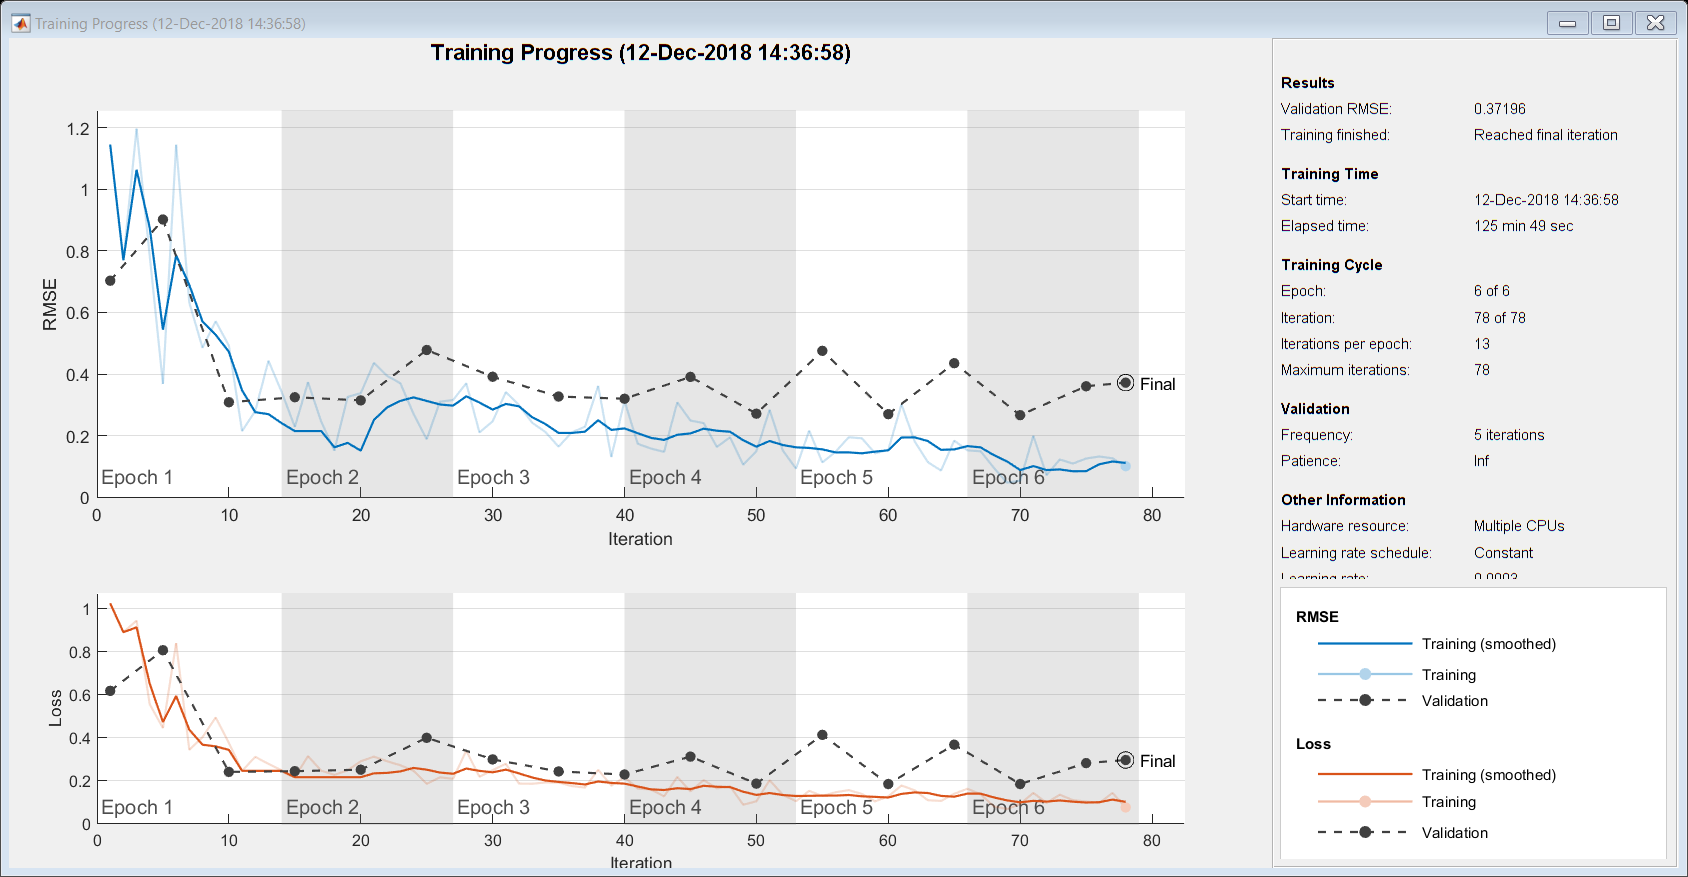

Training across multiple CPUs.


Initializing image normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


tic;
%analyzeNetwork(lgraph);

net = trainNetwork(augimdsTrain,lgraph,options);

% record trainingTime as tt
tt = toc;

## Generate Regression Outputs for Validation Images

Predict the cutting length of the validation images using the fine-tuned network, and calculate the prediction accuracy score.

YPred = predict(net,augimdsValidation);

YActual = imdsValidation.ylabel;

predictionError = abs(YActual - YPred);

avgPredError = mean(predictionError)

avgPredError = single
0.2975


% calculate the accuracy based on a prediction threshold of 0.25 
thr = 0.10;
numCorrect = sum(abs(predictionError) < thr);

numValidationImages = numel(imdsValidation.ylabel);

accuracy = numCorrect/numValidationImages

accuracy = 0.1835

Display four sample validation images with predicted labels and the predicted probabilities of the images having those labels.

% idx = randperm(numel(imdsValidation.Files),4);
% figure
% for i = 1:4
%     subplot(2,2,i)
%     I = readimage(imdsValidation,idx(i));
%     imshow(I)
%     label = YPred(idx(i));
%     title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
% end
% 
% confmat = confusionmat(YPred,imdsValidation.Labels);
% plotconfusion(YPred,imdsValidation.Labels)

Save the training results into a struct array containing:

**NetworkName** - base network name

**AccuracyPercentage** - percentage validation accuracy

**TrainingTime** - average training time

**NumWeights** - total number of network weights to tune

**trainingOptions** - other network training options

**imageAugmentationParameters** - other image 

if ~exist('tt','var')
    tt = 1000;
end
d = datetime;
performance = struct('Accuracy',accuracy,'AveragePredictionError',avgPredError,'TrainingTime',tt)

performance = struct with fields:
                  Accuracy: 0.1835
    AveragePredictionError: 0.2975
              TrainingTime: 8.4246e+03


results = struct(...
'NetworkName',networkName,...
'NetworkSize',size(net),...
'TrainingOptions',options,...
'Performance',performance,...
'dateAndTime',d,...,
'validationData',imdsValidation.ylabel,...
'Predictions',YPred);
tempdir = "C:\Users\Mareim\Downloads\Temporary_Directory\";


### Save the new file in this directory

% create a serialized date string to record the training results
newFilename = ['pretrained-log-',networkName,'-',date,'.mat'];
fullfilename = fullfile(tempdir,newFilename);
save(fullfilename,'results');

### Use the same model for regression output

The classification workflow has produced a Deep Learning model which can, reasonably accurately, distinguish between healthy and worn tools. This could be because the model has an ability to recognize surface roughness. We can put this ability to the test by computing the activations of the lower layers and use a regression model (such as a SVR) to calculate the wear values from each image.

## Research Questions

Under limited data, how can we trust our deeep learning algorithms more?

How can this limited data be beneficial to our training, testing, etc?

### Obtain "Regression labels"

% Run this script to generate regression data
generate_regression_labels;

% % from the image datastore file names, we need the substrings that are
% % unique to each file
% imageNames = imds.Files;
% trimSubstring = 'C:\Users\Mareim\OneDrive - Coventry University\NewImages\Edge\';
% for i = 1:size(imageNames,1)
%     trimmedImageNames{i} = erase(imageNames{i},trimSubstring);
%     % check if the image has a corresponding wear value
%     
% end
% trimmedImageNames =  string(trimmedImageNames)';
% prefix = "A"
% experiment_record = 1;
% % read each image string to extract experiment number and cutting length
% for i = 1:size(trimmedImageNames,1)
%     % experiment record to search
%     experiment_to_match = "A" + experiment_record + "-";
%     % select the subset of image names that matches the current experiment
%     hits = strfind(string(trimmedImageNames),experiment_to_match);
%     % wear values between 0<=l<=10 are excluded
%     hitIndexes = find(not(cellfun('isempty',hits)));
%     experiment = trimmedImageNames(hitIndexes);
%     for ex = 1:size(experiment,1)
%         cuttingLengthLabels(ex) = str2double(cell2mat(extractBetween(tin{1},"A1-W-","M[100]-1.jpg")));
%         % check if this cutting length corresponds to a value in our cutting lengths table
%         if cuttingLen5gthLabels(ex)
%             
%         else
%             
%         end
%     end
% end


## Supporting Function: FindLayerArrayToReplace

function [learnableLayer,classLayer,softmaxProbLayer] = findLayerArrayToReplace(lgraph)

if ~isa(lgraph,'nnet.cnn.LayerGraph')
    error('Argument must be a LayerGraph object.')
end

% Get source, destination, and layer names.
src = string(lgraph.Connections.Source);
dst = string(lgraph.Connections.Destination);
layerNames = string({lgraph.Layers.Name}');

% Find the classification layer. The layer graph must have a single
% classification layer.
isClassificationLayer = arrayfun(@(l) ...
    (isa(l,'nnet.cnn.layer.ClassificationOutputLayer')|isa(l,'nnet.layer.ClassificationLayer')), ...
    lgraph.Layers);

if sum(isClassificationLayer) ~= 1
    error('Layer graph must have a single classification layer.')
end
classLayer = lgraph.Layers(isClassificationLayer);

% Traverse the graph from the end. If a softmax layer is found, return it
% to the outputs to be replaced/removed
isSoftmaxLayer = arrayfun(@(l)...
    (isa(l,'nnet.cnn.layer.SoftmaxLayer')));

if (sum(isSoftmaxLayer)) ~= 1
    error('Layer graph must have a single softmax layer.')
end
softmaxProbLayer = lgraph.Layers(isSoftmaxLayer);

% Traverse the layer graph in reverse starting from the classification
% layer. If the network branches, throw an error.
currentLayerIdx = find(isClassificationLayer);
while true
    
    if numel(currentLayerIdx) ~= 1
        error('Layer graph must have a single learnable layer preceding the classification layer.')
    end
    
    currentLayerType = class(lgraph.Layers(currentLayerIdx));
    isLearnableLayer = ismember(currentLayerType, ...
        ['nnet.cnn.layer.FullyConnectedLayer','nnet.cnn.layer.Convolution2DLayer']);
    
    if isLearnableLayer
        learnableLayer =  lgraph.Layers(currentLayerIdx);
        return
    end
    
    currentDstIdx = find(layerNames(currentLayerIdx) == dst);
    currentLayerIdx = find(src(currentDstIdx) == layerNames);
    
end

end


*Copyright 2018 The MathWorks, Inc.*